# Laboratorio di Automatica (prova del 12 Luglio 2019)

Riccardo Antonello ([riccardo.antonello@unipd.it](mail:riccardo.antonello@unipd.it)) and Angelo Cenedese ([angelo.cenedese@unipd.it](mail:angelo.cenedese@unipd.it)) 

July 12, 2019

Dept. of Information Engineering, University of Padova

## Esercizio 2

In Fig. 2 è riportato lo schema di controllo di velocità a tempo discreto di un motore elettrico a corrente continua, dove $P(z)$ è la versione discretizzata, con il metodo esatto, della funzione di trasferimento del motore a tempo continuo:


$$P(s)\,=\, \frac{\Theta(s)}{U(s)} \,=\, \frac{k_m}{s(T_m s  + 1)}
\qquad\quad\text{con}\qquad\quad
k_m\,=\,5.2\,,\qquad T_m \,=\,0.03$$


da ingresso in tensione $u$ $[V]$ ad uscita in posizione $\vartheta$ $[\mathrm{rad}]$, mentre $C(z)$ è la versione discretizzata della funzione di trasferimento del controllore di velocità a tempo continuo:


$$C(s)\,=\,\frac{U(s)}{E(s)}\,=\, \;\frac{k}{s}\,\left(\frac{1+\tau\,s}{1+\alpha\,\tau\,s}\right)\qquad\quad\text{con}\qquad\quad \alpha=0.17\,,\qquad\tau=0.015\,,\qquad k\geq 0$$


con ingresso l'errore di velocità $e\,[\mathrm{rad/s}]$ ed uscita la tensione di comando $u\,[\mathrm{V}]$. Il filtro $H(z)$ è un filtro derivatore reale del tipo:


$$H(z) \,=\, \frac{\Omega(s)}{\Theta(s)} \,=\, \frac{1-z^{-N}}{N T_s}\qquad\text{con}\qquad N=3$$


utilizzato per ricavare la velocità $\omega$ del motore, a partire dalla misura di posizione $\vartheta$.  

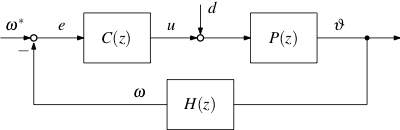

**Figura 2**: Sistema di controllo a tempo discreto.

Si supponga di discretizzare il controllore con i metodi di: (a) Eulero in Avanti (Forward Euler); (b) Eulero all'Indietro (Backward Euler); (c) Tustin.

Per il sistema di controllo, si consideri un periodo di campionamento pari a $T_s=10\,\mathrm{ms}$.

Utilizzando *soltanto* le routines del Control System Toolbox (CST), per ciascuno dei metodi di discretizzazione proposti per il controllore si svolgano i seguenti punti:

1) Utilizzando il luogo delle radici, determinare per quali valori del guadagno $k$ del controllore il sistema di controllo a catena chiusa è BIBO stabile. 

*Soluzione*.

Discretizzazione di $P(s)$ con il metodo esatto:

%   plant params
Tm = 0.03;
km = 5.2;
mu = 1;

%   plant tf (continuous-time)
sysP = tf(km, [Tm, 1, 0]);

%   plant discretization
Ts = 10e-3;
sysP = c2d(sysP, Ts, 'zoh');
zpk(sysP)


ans =
 
  0.0077789 (z+0.8949)
  --------------------
    (z-1) (z-0.7165)
 
Sample time: 0.01 seconds
Discrete-time zero/pole/gain model.



Definizione del filtro derivatore (speed filter):

%   speed filter
z = tf('z', Ts);
sysH = (1-z^-3)/(3*Ts);

 Discretizzazione di $C(s)$ con il metodo di Eulero in Avanti (Forward Euler):

%   controller params
tau = 0.015;
a = 0.17;

%   controller discretization (Forward Euler)
q = (z-1)/Ts;
sysC_FE = minreal( (1/q)*(tau*q + 1)/(a*tau*q + 1) );
zpk(sysC_FE)


ans =
 
  0.058824 (z-0.3333)
  -------------------
    (z+2.922) (z-1)
 
Sample time: 0.01 seconds
Discrete-time zero/pole/gain model.



Tracciamento del luogo delle radici:

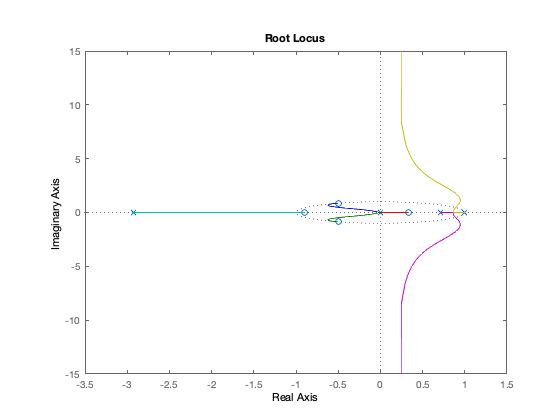

%   loop tf
sysL_FE = minreal( sysC_FE*sysP*sysH );

%   root locus
figure(1);
rlocus(sysL_FE);

Il sistema in catena chiusa è instabile per ogni scelta del guadagno $k \geq 0$ del controllore.

Discretizzazione di $C(s)$ con il metodo di Eulero all'Indietro (Backward Euler):

%   controller discretization (Backward Euler)
q = (1-z^-1)/Ts;
sysC_BE = minreal( (1/q)*(tau*q + 1)/(a*tau*q + 1) );
zpk(sysC_BE)


ans =
 
  0.01992 z (z-0.6)
  -----------------
  (z-1) (z-0.2032)
 
Sample time: 0.01 seconds
Discrete-time zero/pole/gain model.



Tracciamento del luogo delle radici:

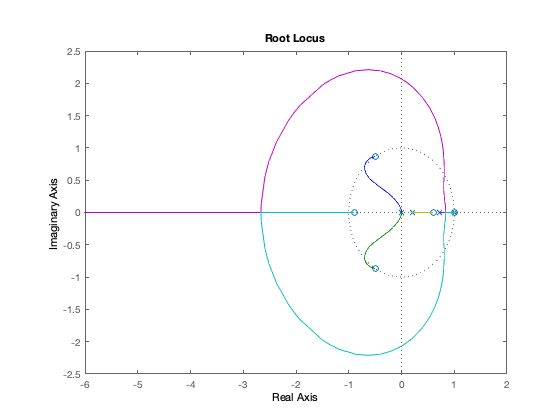

%   loop tf
sysL_BE = minreal( sysC_BE*sysP*sysH );

%   root locus
figure(2);
rlocus(sysL_BE);
hold on;

Determinazione del massimo guadagno $\bar{k}$ per il quale il sistema di controllo in catena chiusa è (internamente) stabile:

%   gain margin
Gm_BE = margin(sysL_BE)

Gm_BE = 20.5369

 Discretizzazione di $C(s)$ con il metodo di Tustin:

%   controller discretization (Tustin)
q = 2/Ts*(z-1)/(z+1);
sysC_TU = minreal( (1/q)*(tau*q + 1)/(a*tau*q + 1) ); %   alternative: use c2d
zpk(sysC_TU)


ans =
 
  0.013245 (z+1) (z-0.5)
  ----------------------
     (z-1) (z+0.3245)
 
Sample time: 0.01 seconds
Discrete-time zero/pole/gain model.



Tracciamento del luogo delle radici:

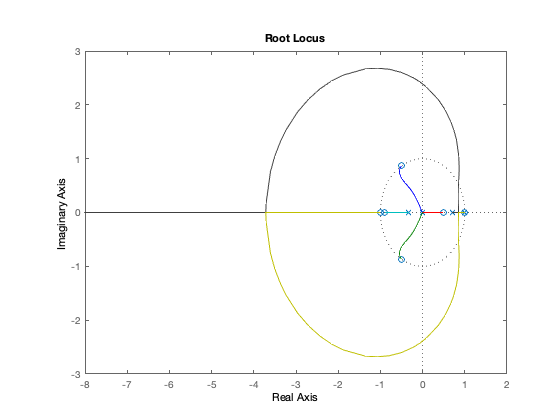

%   loop tf
sysL_TU = minreal( sysC_TU*sysP*sysH );

%   root locus
figure(3);
rlocus(sysL_TU);
hold on;

Determinazione del massimo guadagno $\bar{k}$ per il quale il sistema di controllo in catena chiusa è (internamente) stabile:

%   gain margin
Gm_TU = margin(sysL_TU)

Gm_TU = 18.4912

2) Si imposti il guadagno del controllore al valore $k = \bar{k}/2$, dove $\bar{k}$ è il valore massimo di guadagno  per il quale il sitema di controllo a catena chiusa è BIBO stabile. Con tale valore di guadagno, calcolare i poli del sistema in catena chiusa, e mostrarli sul luogo delle radici tracciato al punto 1.

*Soluzione*.

Con controllore discretizato con il metodo di Eulero all'Indietro (Backward Euler):

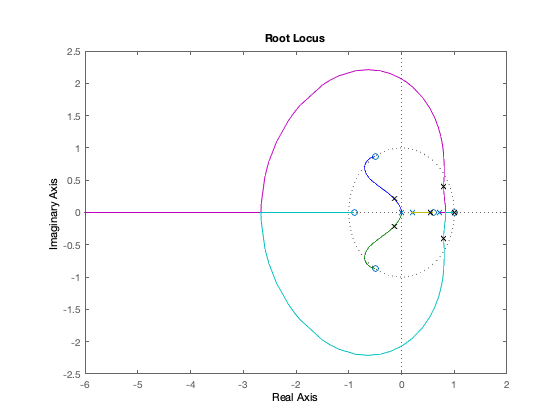

%   controller gain
k_BE = Gm_BE*0.5;

%   closed-loop tf (ref to out)
sysT_BE = feedback(k_BE*sysL_BE, 1);

%   closed-loop poles
p = pole(sysT_BE);

%   plot closed-loop poles
figure(2);
plot(p, 'xk');

Con controllore discretizato con il metodo di Tustin:

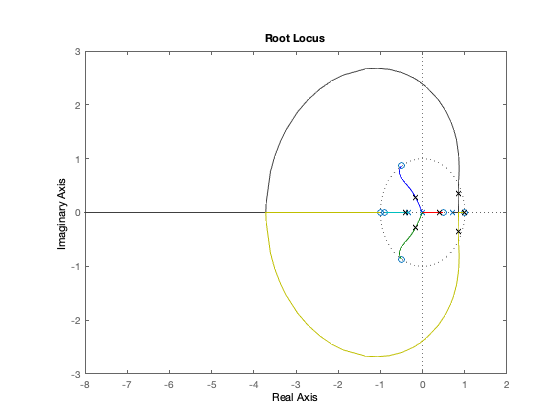

%   controller gain
k_TU = Gm_TU*0.5;

%   closed-loop tf (ref to out)
sysT_TU = feedback(k_TU*sysL_TU, 1);

%   closed-loop poles
p = pole(sysT_TU);

%   plot closed-loop poles
figure(3);
plot(p, 'xk');

3) Con il valore di guadagno impostato al punto 2, determinare la risposta al gradino unitario del sistema di controllo in catena chiusa, da riferimento $\omega^*$ a uscita $\omega$, e mostrarla in un grafico. Si determinino inoltre sovraelongazione percentuale e tempo di assestamento al $5\%$.

*Soluzione*.

Con controllore discretizato con il metodo di Eulero all'Indietro (Backward Euler):

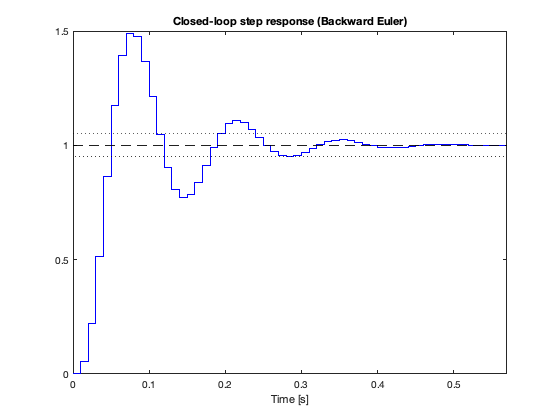

%   closed-loop step response
[y, t] = step(sysT_BE);

%   plot closed-loop response
figure;
stairs(t, y, 'b');
hold on;
plot([t(1), t(end)], [1, 1], 'k--');
plot([t(1), t(end)], 0.95*[1, 1], 'k:');
plot([t(1), t(end)], 1.05*[1, 1], 'k:');
xlim([t(1), t(end)]);
xlabel('Time [s]');
title('Closed-loop step response (Backward Euler)')


%   settling time and overshoot
S = stepinfo(y, t, 1, 'SettlingTimeThreshold', 0.05);

Tempo di assestamento al $5\%$:

S.SettlingTime

ans = 0.2805

Sovraelongazione %:

S.Overshoot

ans = 48.9879

Con controllore discretizato con il metodo di Tustin:

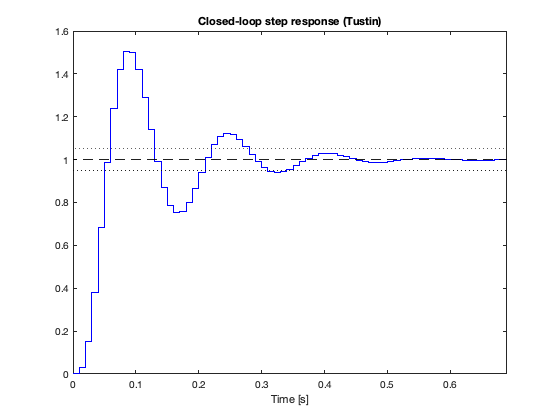

%   closed-loop step response
[y, t] = step(sysT_TU);

%   plot closed-loop response
figure;
stairs(t, y, 'b');
hold on;
plot([t(1), t(end)], [1, 1], 'k--');
plot([t(1), t(end)], 0.95*[1, 1], 'k:');
plot([t(1), t(end)], 1.05*[1, 1], 'k:');
xlim([t(1), t(end)]);
xlabel('Time [s]');
title('Closed-loop step response (Tustin)')


%   settling time and overshoot
S = stepinfo(y, t, 1, 'SettlingTimeThreshold', 0.05);

Tempo di assestamento al $5\%$:

S.SettlingTime

ans = 0.3358

Sovraelongazione %:

S.Overshoot

ans = 50.4040